# Ex 2

clear;clc;close all;

f = @(x) exp(x/2)

f = function_handle with value:
    @(x)exp(x/2)



x = linspace(1, 9, 5); % Degré <= 4 implique 5 points
y = f(x); % Valeurs des fcts

% Matrice vander calculée automatiquement
V = vander(x); 

y = y';
c = V\y % Coefficients

c =     0.0374
   -0.4246
    2.2590
   -3.5968
    3.3737


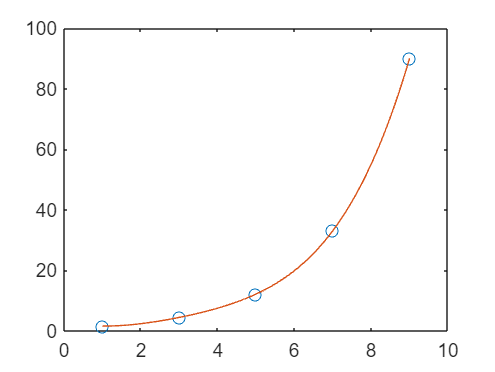


% Affichage de la fonction
xx = linspace(1, 9, 1e3); % Echantillons
p = polyval(c, xx);
plot(x, y, 'o', xx, p);

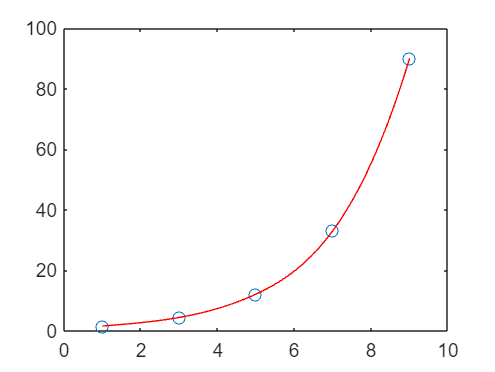


% Spline :
pp = spline(x, y, xx);

plot(x, y, 'o', xx, pp, 'r');